# From Many-Body Wave Function Description to Density Functional Theory

## Many-Electron Quantum Mechanics

Solving the many-electron Schrödinger equation, $\hat H\Psi_0(\mathbf{r}_1,\mathbf{r}_2,\cdots \mathbf{r}_N) =E_0\Psi_0(\mathbf{r}_1,\mathbf{r}_2,\cdots \mathbf{r}_N)$ with Hamiltonian in Eq. (3), for the ground state wave function $\Psi_0(\mathbf{r}_1,\mathbf{r}_2,\cdots \mathbf{r}_N)$ and energy $E_0$, becomes a daunting task even for relatively small molecules. An alternative route is provided by shifting the focus from many-electron wave function to the electron density $\rho(\mathbf{r})$, similar to the Thomas-Fermi model, but in a systematic way. This shift is enabled by the Hohenberg and Kohn theorems. 

- The first theorem sets **one-to-one correspondence between the ground state electron density** $\rho_0(\mathbf{r})$ and the electrostatic potential of immobile nuclei, referred to as **external potential**. 

- The second theorem establishes the variational principle formulated in terms of electron density as a basic variable: the energy functional of electron density $E[\rho]$ (given in Eq. (24) below) can be defined, such that the minimal value of the functional equals the ground state energy and it is attained for and only for $\rho(\mathbf{r}) =\rho_0(\mathbf{r})$: $E[\rho_0]=\min   \Bigl\{ E[\rho]\Bigr\}=E_0$. 

It is not known how to construct energy functional $E[\rho]$ in an exact way, and various approximations are used to write it down, the simplest (and the crudest) of them being the Thomas-Fermi approximation. The notion of energy functional of electron density is the key notion on which the density functional theory (DFT) is built and named after.

## Single-Electron Density as a Basic Variable

For quantum mechanical many-electron system the electron density, $\rho(\mathbf{r})$, is found by calculating the expectation value of the single-particle density operator 


$$\hat\rho(\mathbf{r})=\sum_{i=1}^N \delta^3\left(\mathbf{r}-\hat \mathbf{r}_i\right)$$


in a state $| \Psi \rangle$ described by the many-electron wave function $\Psi\left(\mathbf{r}_1,\mathbf{r}_2, \cdots \mathbf{r}_N\right)= \langle \mathbf{r}_1, \mathbf{r}_2, \cdots \mathbf{r}_N|\Psi \rangle$. When used as argument of $\Psi$, unless explicitely specified otherwise, variables$\left\{\mathbf{r}_i\right\}=\left\{ ( \mathbf{r}_i , \sigma_i)\right\}$include both coordinates and spins of electrons. Many-electron wave function is antisymmetric with respect to exchanging coordinate and spin variables of any two electrons $\Psi\left(\mathbf{r}_1,\cdots\mathbf{r}_i, \cdots  \mathbf{r}_j,\cdots  \mathbf{r}_N\right)= - \Psi\left(\mathbf{r}_1,\cdots \mathbf{r}_j, \cdots \mathbf{r}_i,\cdots \mathbf{r}_N\right)$ and is unit normalized $\int \left|\Psi\left(\mathbf{r}_1,\mathbf{r}_2, \cdots \mathbf{r}_N\right)\right|^2 d \mathbf{r}_1 d\mathbf{r}_2 \cdots d \mathbf{r}_N=1$, with the summation over spin variables of all $N$ electrons also implied, $\int d\mathbf{r}_i \equiv \displaystyle\sum_{\sigma_i}\int d\mathbf{r}_i$.


$$\rho(\mathbf{r})  =\langle\Psi|\hat{\rho}(\mathbf{r})| \Psi\rangle=\sum^N_{i=1} \int \delta^3\left(\mathbf{r}-\mathbf{r}_i\right)\left|\Psi\left(\mathbf{r}_1,\mathbf{r}_2, \cdots \mathbf{r}_N\right)\right|^2 d \mathbf{r}_1 \mathbf{r}_2 \cdots d \mathbf{r}_N \\ \qquad =\sum_{\sigma_1=-\frac{1}{2}}^{\frac{1}{2}}\int\left|\Psi\left(\mathbf{r}, \mathbf{r}_2, \cdots \mathbf{r}_N\right)\right|^2 d \mathbf{r}_2 d \mathbf{r}_3 \cdots d \mathbf{r}_N+\sum_{\sigma_2=-\frac{1}{2}}^{\frac{1}{2}}\int\left|\Psi\left(\mathbf{r}_1, \mathbf{r}, \cdots \mathbf{r}_N\right)\right|^2 d \mathbf{r}_1 d \mathbf{r}_3 \cdots d \mathbf{r}_N+\cdots \\ \qquad =\sum_{\sigma_1=-\frac{1}{2}}^{\frac{1}{2}}N \int\left|\Psi\left(\mathbf{r},\mathbf{r}_2,\cdots \mathbf{r}_N\right)\right|^2 d \mathbf{r}_2 \cdots d \mathbf{r}_N =\sum_{\sigma_1,\sigma_2,...\sigma_N=-\frac{1}{2}}^{\frac{1}{2}} N \int\left|\Psi\left(\mathbf{r},\sigma_1,\mathbf{r}_2,\sigma_2,\cdots \mathbf{r}_N,\sigma_N\right)\right|^2 d \mathbf{r}_2 \cdots d \mathbf{r}_N , \qquad (1)$$


where we separated expicitly spin and spatial coordinates in the final expression of Eq. (1) and used: $\delta^3 (\mathbf{r}-\hat \mathbf{r}_i) \Psi\left(\mathbf{r}_1, \mathbf{r}_2,\cdots \mathbf{r}_i,\cdots\mathbf{r}_N\right) = \delta^3 (\mathbf{r}- \mathbf{r}_i) \Psi\left(\mathbf{r}_1, \mathbf{r}_2,\cdots \mathbf{r}_i,\cdots \mathbf{r}_N\right)$. 

Separating coordinate and spin variables explicitly we have


$$\hat\rho(\mathbf{r})=\hat\rho_{\uparrow}(\mathbf{r})+\hat\rho_{\downarrow}(\mathbf{r})= \sum_{i=1}^N \delta^3\left(\mathbf{r}-\hat \mathbf{r}_i\right)(\delta_{\hat \sigma_i,\frac{1}{2}}+\delta_{\hat \sigma_i,-\frac{1}{2}})=\sum_{i=1}^N \delta^3\left(\mathbf{r}-\hat \mathbf{r}_i\right),$$


where $\hat \sigma_i$ is $z$-component of spin (vector) operator of $i$-th electron with two possible eigen values $\pm \frac{1}{2}$, hence $\delta_{\hat \sigma_i,\frac{1}{2}}+\delta_{\hat \sigma_i,-\frac{1}{2}}=1$, see [here](https://arxiv.org/pdf/1206.2234.pdf). Spin resolved single-electron density operators $\hat \rho_{\uparrow}(\mathbf{r})$ and $\hat \rho_{\downarrow}(\mathbf{r})$ have following expectation values in state $| \Psi \rangle$


$$\rho_{\sigma} (\mathbf{r})=\langle\Psi|\hat{\rho}_{\sigma}(\mathbf{r})| \Psi\rangle=\langle\Psi| \sum^N_{i=1}\delta^3(\mathbf{r}-\hat \mathbf{r}_i) \delta_{\hat \sigma_i,\sigma}  | \Psi\rangle=N \int\left|\Psi\left(\mathbf{r},\sigma,\mathbf{r}_2,\cdots \mathbf{r}_N\right)\right|^2 d \mathbf{r}_2 \cdots d \mathbf{r}_N=N \sum_{\sigma_2,...,\sigma_N=-\frac{1}{2}}^{\frac{1}{2}}\int\left|\Psi\left(\mathbf{r},\sigma,\mathbf{r}_2,\sigma_2,\cdots \mathbf{r}_N, \sigma_N\right)\right|^2 d \mathbf{r}_2 \cdots d \mathbf{r}_N,$$


where again, we separated expicitly all spin and spatial coordinates in the final expression.

Due to unit normalization of the wave function, integrating the electron density over the whole $R^3$ space yields the total number of electrons


$$\begin{array}{cc}\int \rho(\mathbf{r})d \mathbf{r} =N.& \qquad (2)\\ \end{array}$$


Let's try to express the total electronic energy (expectation value of the Hamiltonian in many-body state) in terms of $\rho(\mathbf{r})$ [*]. The Hamiltonian of generic $N$-electron system in atomic Hartree units is 


$$\begin{array}{cc}\hat{H} =\hat{T}+\hat{V}_{e n}+\hat{V}_{e e}  =-\frac{1}{2} \sum_{i=1}^{N} \nabla_{i}^{2}-\sum_{i=1}^{N} \sum_{I=1}^{N_{n}} \frac{Z_{I}}{\left|\mathbf{r}_{i}-\mathbf{R}_{I}\right|}+\frac{1}{2} \sum_{j=1(j\neq i)}^{N} \sum_{i=1}^{N} \frac{1}{\mid \mathbf{r}_{i}-\mathbf{r}_{j} \mid},& \qquad (3)\\ \end{array}$$


where upper case $\mathbf{R}_I$ denote coordinates of (infinitely heavy and hence immobile in Born-Oppenheimer approximation) $N_n$ nuclei with charges $Z_I$, and $\mathbf{r}_i$ are coordinates of $N$ electrons. 

Our aim is to determine ground state configuration of electrons (electron density) and positions of nuclei that minimizes the expectation value of 


$$\hat H+ E_{nn}= \hat H+\sum^{N_n}_{I'=1 (I'>I)} \sum^{N_n}_{I=1}   \frac{Z_IZ_{I'} }{|\mathbf{R}_I -\mathbf{R}_{I'} |  }.$$


In the following we will assume that $\mathbf{R}_I$ are ground state coordinates of the nuclei and only consider the electron degrees of freedom. 

### Electron-Nucleus Interaction

Suppose that we have solved the many-body Schrödinger equation for these fixed values of $\mathbf{R}_I$ and have obtained the $N$-electron wave function.

The expectation value of the electron-nucleus interaction operator is given by


$$\begin{array}{cc}E_{en} = \left\langle\Psi\left(\mathbf{r}_{1}, \mathbf{r}_2,\cdots \mathbf{r}_{n}\right)\left|\hat{V}_{en}\right| \Psi\left(\mathbf{r}_{1},\mathbf{r}_2, \cdots \mathbf{r}_{n}\right)\right\rangle=-\sum_{i=1}^{N} \sum_{I=1}^{N_{n}} \int \frac{Z_{I}}{\left|\mathbf{r}_{i}-\mathbf{R}_{I}\right|}\left|\Psi\left(\mathbf{r}_{1},\mathbf{r}_2, \cdots \mathbf{r}_{N}\right)\right|^{2} d \mathbf{r}_{1} \mathbf{r}_2\cdots d \mathbf{r}_{N}.& \qquad (4)\\ \end{array}$$


Let's expand the sum over the electronic index $i$


$$\begin{array}{cc}E_{en}=-\sum_{I=1}^{N_{n}}\left[\int \frac{Z_{I}}{\left|\mathbf{r}_{1}-\mathbf{R}_{I}\right|}\left|\Psi\left(\mathbf{r}_{1}, \mathbf{r}_2, \cdots \mathbf{r}_{N}\right)\right|^{2} d \mathbf{r}_{1}\mathbf{r}_2 \cdots d \mathbf{r}_{N}\right. \left.+\int \frac{Z_{I}}{\left|\mathbf{r}_{2}-\mathbf{R}_{I}\right|}\left|\Psi\left(\mathbf{r}_{1}, \mathbf{r}_2,\cdots \mathbf{r}_{N}\right)\right|^{2} d \mathbf{r}_{1}\mathbf{r}_2 \cdots d \mathbf{r}_{N}+\cdots\right].& \qquad (5)\\ \end{array}$$


For each of the $N$ terms in the sum in Eq. (5), we separate the integral over the variable in the Coulombic terms from the others. 


$$\begin{array}{cc}\begin{array}{rll}E_{en}=&-\sum_{I=1}^{N_{n}}\left[\int \frac{Z_{I}}{\left|\mathbf{r}_{1}-\mathbf{R}_{I}\right|} d \mathbf{r}_{1} \int\left|\Psi\left(\mathbf{r}_{1},\mathbf{r}_2, \cdots \mathbf{r}_{N}\right)\right|^{2} d \mathbf{r}_{2} d \mathbf{r}_{3} \cdots d \mathbf{r}_{N}\right. \\&\left.+\int \frac{Z_{I}}{\left|\mathbf{r}_{2}-\mathbf{R}_{I}\right|} d \mathbf{r}_{2} \int\left|\Psi\left(\mathbf{r}_{1}, \mathbf{r}_2,\cdots \mathbf{r}_{N}\right)\right|^{2} d \mathbf{r}_{1} d \mathbf{r}_{3} \cdots d \mathbf{r}_{N}+\cdots+\int \frac{Z_{I}}{\left|\mathbf{r}_{N}-\mathbf{R}_{I}\right|} d \mathbf{r}_{N} \int\left|\Psi\left(\mathbf{r}_{1},\mathbf{r}_2, \cdots \mathbf{r}_{N}\right)\right|^{2} d \mathbf{r}_{1} d \mathbf{r}_{2}\cdots d\mathbf{r}_{N-1}\right].\end{array}& \qquad (6)\\ \end{array}$$


In each term in the right-hand-side of Eq. (6), the second integral is the definition of $\rho(\mathbf{r})$/N as given in Eq. (1), and hence, Eq. (6) may be written as


$$\begin{array}{cc}\begin{array}{rll}E_{en}&=-\frac{1}{N} \sum_{I=1}^{N_{n}}\left[\int \frac{Z_{I}}{\left|\mathbf{r}_{1}-\mathbf{R}_{I}\right|} \rho\left(\mathbf{r}_{1}\right) d\mathbf{r}_1+\int \frac{Z_{I}}{\left|\mathbf{r}_{2}-\mathbf{R}_{I}\right|} \rho\left(\mathbf{r}_{2}\right)d\mathbf{r}_2+\cdots+\int \frac{Z_{I}}{\left|\mathbf{r}_{N}-\mathbf{R}_{I}\right|} \rho\left(\mathbf{r}_{N}\right)d\mathbf{r}_N\right] \\&=-\sum_{I=1}^{N_{n}} \int \rho(\mathbf{r}) \frac{Z_{I}}{\left|\mathbf{r}-\mathbf{R}_{I}\right|} d \mathbf{r}=\int \rho(\mathbf{r}) V_{ext}(\mathbf{r}) d \mathbf{r},\end{array}& \qquad (7)\\ \end{array}$$


with external potential $V_{ext}(\mathbf{r})=\frac{\delta E_{en}[\rho]}{\delta \rho(\mathbf{r})}=-\sum^{N_n}_{I=1}\frac{Z_{I}}{\left|\mathbf{r}-\mathbf{R}_{I}\right|}$ and the following density functional: $E_{en}[\rho]=\int \rho(\mathbf{r}) V_{ext}(\mathbf{r}) d \mathbf{r}$. 

### Electron-Electron Interaction

The electron-electron interaction term, however, cannot be written in terms of the single-particle density. Instead, it can be written in terms of the two-particle (two-electron) density 


$$\begin{array}{cc}E_{e e}=\int \int  \frac{\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|} d \mathbf{r} d \mathbf{r}^{\prime},& \qquad (8)\\ \end{array}$$


where

 
$$\hat \rho^{(2)}( \mathbf{r},\mathbf{r'})=\frac{1}{2}\sum_{j\neq i}^{N}\sum_{i=1}^{N}  \delta^3 (\mathbf{\hat r}_i -\mathbf{r}) \delta^3 (\mathbf{\hat r}_j -\mathbf{r'}) =\hat \rho(\mathbf{r}) \hat \rho(\mathbf{r'})/2-\delta(\mathbf{r}-\mathbf{r'}) \hat \rho(\mathbf{r})/2  \qquad (8a)$$


and 


$$\rho^{(2)}( \mathbf{r},\mathbf{r'})=\frac{1}{2}\sum_{j\neq i}^{N}\sum_{i=1}^{N}  \langle \Psi | \delta^3 (\mathbf{\hat r}_i -\mathbf{r}) \delta^3 (\mathbf{\hat r}_j -\mathbf{r'})  |\Psi \rangle=\frac{N (N-1)}{2}\sum_{\sigma,\sigma'}\int \left|\Psi\left(\mathbf{r}, \mathbf{r'},   \mathbf{r}_3,\cdots \mathbf{r}_N\right)\right|^2 d \mathbf{r}_3 \cdots d \mathbf{r}_N.\end{array}$$


Eq. (8) can be derived in a similar manner to $E_{en}$. 

We will represent $\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)$ as a sum of density-density interaction and the correction term,


$$\begin{array}{cc}\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)= \rho(\mathbf{r}) \rho(\mathbf{r}^{\prime})/2+\Delta \rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right),& \qquad (9)\\ \end{array}$$


where from Eq. (8a) we get

$\Delta \rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)= \langle  \Psi|    \hat \rho(\mathbf{r})  \hat \rho(\mathbf{r'})  |\Psi \rangle/2 -\rho(\mathbf{r}) \big(\delta^3(\mathbf{r} -\mathbf{r'}) +\rho(\mathbf{r'})\big)/2 \qquad (9a)$.

$\rho(\mathbf{r}) \rho(\mathbf{r'})$ contains self-interaction of electrons, while $\rho^{(2)}( \mathbf{r},\mathbf{r'})$ does not, since summation in Eq. (8a) is restricted to $j\neq i$. $\Delta\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)$ term subtracts self-interaction from $\rho(\mathbf{r}) \rho(\mathbf{r'})$, see Excercise 1, and moreover it includes both exchange and correlation corrections, the latter, stemming from truly many-body nature of $N$-electron wave function, is absent by definition of Hartree-Fock approximation. 

The ground state average of the electron-electron interaction energy may then be written using decomposition in Eq. (9) as


$$\begin{array}{cc}E_{e e}=\frac{1}{2} \int \int  \frac{\rho_0(\mathbf{r}) \rho_0\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|} d \mathbf{r} d \mathbf{r}^{\prime}+\Delta E_{e e},& \qquad (10)\\ \end{array}$$
 

where the second term comes from the correction term $\Delta \rho_0^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)$.

### Kinetic Energy

The kinetic energy operator contains derivative terms, and its expectation value in state $| \Psi \rangle$ is:


$$\begin{array}{cc}T=-\frac{1}{2} \int  \Psi^{*}\left(\mathbf{r}_{1}, \mathbf{r}_2,\cdots \mathbf{r}_{N}\right) \sum^N_{i=1}\nabla_i^{2} \Psi\left(\mathbf{r}_{1},\mathbf{r}_2, \cdots \mathbf{r}_{N}\right)d \mathbf{r}_1 \mathbf{r}_2\cdots d \mathbf{r}_N.& \qquad (11)\\ \end{array}$$


**Depending how the kinetic energy is modeled, DFT has two implementations** as depicted in Fig. 1: 

- orbital-free or pure DFT implementation in terms of purely electron density 

and 

- Kohn-Sham single-particle orbital approach, implemented with the help of a system of fictituous non-interacting electrons that has the same ground state density as interacting electron system. These non-interacting electrons move in the effective potential that in its turn denepends on the electron density. 

#### 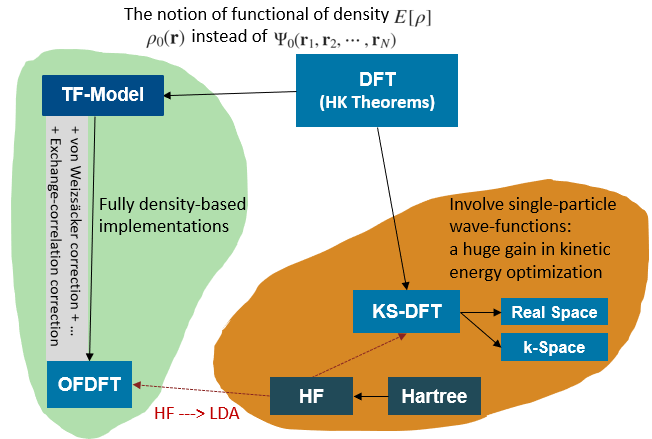

Figure 1: Two implementations of DFT, purely density based (orbital-free) and Kohn-Sham DFT

#### Orbital-Free DFT

Orbital-free (pure) DFT (OFDFT) is an approach where kinetic energy functional is constructed directly from electron density, e.g. by extending the Thomas-Fermi approximation:


$$T[\rho]=T_{\mathrm{TF}}[\rho]+\lambda T_{\mathrm{vW}}[\rho]+\cdots,$$


where $T_{\mathrm{TF}}[\rho]$ is the Thomas-Fermi kinetic energy functional, 


$$T_{\mathrm{TF}}=C_F \int \rho^{5 / 3}(\mathbf{r})d \mathbf{r} \end{array},$$


 with $C_F = \frac{3}{10}\left(3 \pi^2\right)^{2 / 3}$, $T_{\mathrm{vW}}$ is the semilocal von Weizsäcker functional, 


$$T_{\mathrm{vW}}[\rho] =\frac{1}{2} \int \Big(\nabla \sqrt{\rho(\mathbf{r})} \Big)^2 d \mathbf{r},$$
 

and $\lambda$ is a numerical constant controlling the amount of admixture of von Weizsäcker correction.

We will cover this implementation in live script *Orbital-Free DFT,* where electron-electron interaction functional will include exchange-correlation correction of the Hartree term. The reader may choose to skip from here to the section on Hohenberg-Kohn Theorems, then continue with live script *Orbital-Free DFT* and after that continue with the Kohn-Sham DFT section.

#### **Kohn-Sham DFT**

Modeling kinetic energy functional directly, guessing its dependence on density, turns out to be one of the main limiting factors of the accuracy of the OFDFT. In order to tackle the kinetic energy, Kohn and Sham (KS) made the key assumption of DFT, so called non-interacting (NI) $v$-representable assumption: Namely that there is a fictitious system of non-interacting electrons moving in the effective KS potential (KS potential we will derive explicitely in the live script on KS-DFT), that has **exactly same ground state electron density as the interacting system** of interest. It is not known if a given interacting $N$-electron system is NI $v$-representable, but in case it is, the KS-DFT treatment is an exact approach for studying its ground state properties. Many-body ground state wave function of non-interacting KS electrons then is constructed as a single Slater determinant:


$$\Psi^0_{ \mathrm{KS}}\left(\mathbf{r}_1, \mathbf{r}_2, \ldots \mathbf{r}_N\right)=\frac{1}{\sqrt{N !}} \left|\begin{array}{cccccccccccccc}\psi^0_1\left(\mathbf{r}_1\right) & \psi^0_2\left(\mathbf{r}_1\right) & \cdots & \psi^0_N\left(\mathbf{r}_1\right) \\\psi^0_1\left(\mathbf{r}_2\right) & \psi^0_2\left(\mathbf{r}_2\right) & \cdots & \psi^0_N\left(\mathbf{r}_2\right) \\\vdots & \vdots & \ddots & \vdots \\\psi^0_1\left(\mathbf{r}_N\right) & \psi^0_2\left(\mathbf{r}_N\right) & \cdots & \psi^0_N\left(\mathbf{r}_N\right)\\ \end{array}\right|,$$


with $\psi^0_i$ orthonormalized single-particle KS spin-orbitals that include both coordinate and spin parts of the single-particle wave function. 

The ground state electron density can be written in terms of these orbitals as 


$$\begin{array}{cc}\rho_0(\mathbf{r})=N \sum_{\sigma_1}\int\left|\Psi^0_{\mathrm{KS}}\left(\mathbf{r},\mathbf{r}_2,\cdots \mathbf{r}_N\right)\right|^2 d \mathbf{r}_2 \cdots d \mathbf{r}_N=\sum_{n=1}^{N}\left|\psi^0_{n}(\mathbf{r})\right|^{2}& \qquad (12)\\ \end{array}$$


Writing the electron density as in Eq. (12) suggests that we write the kinetic energy of the interacting electron system as the sum of the kinetic energies of the non-interacting orbitals $T_{KS}=-\frac{1}{2} \sum_{n=1}^{N}  \int\psi_{n}^{0*}(\mathbf{r}) \nabla^{2} \psi^0_{n}(\mathbf{r}) d \mathbf{r}$, however, this of course is not going to equal the kinetic energy of the real many-particle system. To account for the discrepancy we express the kinetic energy of interacting electron system as the single-particle kinetic energy plus a correction


$$T=T_{KS}+(T-T_{KS})=-\frac{1}{2} \sum_{n=1}^{N} \int  \psi_{n}^{0*}(\mathbf{r}) \nabla^{2} \psi^0_{n}(\mathbf{r})d \mathbf{r} +\Delta T. \qquad (13)$$


Finally putting together all contributions, the total ground state energy of the interacting $N$-electron ststem is


$$\begin{array}{cc}E_0=-\frac{1}{2} \sum_{n=1}^{N} \int \psi_{n}^{0*}(\mathbf{r}) \nabla^{2} \psi^0_{n}(\mathbf{r})d \mathbf{r}  +\int \rho_0(\mathbf{r}) V_{ext}(\mathbf{r}) d \mathbf{r}+\frac{1}{2} \int\int \frac{\rho_0(\mathbf{r}) \rho_0\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|}d \mathbf{r} d \mathbf{r}^{\prime} +\Delta T+\Delta E_{e e}.& \qquad (14)\\ \end{array}$$


### Electron-Electron Interaction

The last two terms $\Delta T$ and $\Delta E_{e e}$ in Eq. (14) play a crucial role in KS-DFT. Without loss of generality, we will represent their sum in terms of the **exchange-correlation** energy as: 


$$\begin{array}{cc}\Delta E_{ee}+\Delta T=E_{x c}=\int  \epsilon_{x c}(\mathbf{r})  \rho_0(\mathbf{r}) d \mathbf{r},& \qquad (15)\\ \end{array}$$


where exchange-correlation energy per electron is denoted as $\epsilon_{xc}(\mathbf{r})$.

Then, the total ground state energy may be written as


$$\begin{array}{cc}E_0=-\frac{1}{2} \sum_{n=1}^{N} \int d \mathbf{r} \psi_{n}^{0*}(\mathbf{r}) \nabla^{2} \psi^0_{n}(\mathbf{r}) +\int \rho_0(\mathbf{r}) V_{ext}(\mathbf{r}) d \mathbf{r}+\frac{1}{2} \int \int d \mathbf{r} d \mathbf{r}^{\prime} \frac{\rho_0(\mathbf{r}) \rho_0\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|}+\int d \mathbf{r} \epsilon_{x c}(\mathbf{r}) \rho_0(\mathbf{r}) .& \qquad (16)\\ \end{array}$$


Having expression of the ground state energy as in Eq. (16), we can reverse the problem and define energy functional of some "helper" orthonormalized single-particle orbitals as (without further specifying the expression for the exchange-correlation energy per electron at this moment. $\epsilon_{xc}(\mathbf{r})$ can show arbitrarily complicated, non-local dependence on electron density, its gradients, etc.): 


$$E[\left\{\psi_n,\psi^*_n\right\}]=-\frac{1}{2} \sum_{n=1}^{N} \int \psi_{n}^{*}(\mathbf{r}) \nabla^{2} \psi_{n}(\mathbf{r}) d \mathbf{r} +\int \rho(\mathbf{r}) V_{ext}(\mathbf{r}) d \mathbf{r}+\frac{1}{2} \int \int  \frac{\rho(\mathbf{r}) \rho\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|}d \mathbf{r} d \mathbf{r}^{\prime}+\int  \epsilon_{x c}(\mathbf{r}) \rho(\mathbf{r}) d \mathbf{r}\qquad (16b)$$



$$\int \psi^*_i(\mathbf{r}) \psi_j(\mathbf{r}) d\mathbf{r} = \delta_{ij}$$
      
$$\rho(\mathbf{r})=\sum_{n=1}^{N}\left|\psi_{n}(\mathbf{r})\right|^{2}$$


and search variationally for the orbitals that minimize this energy functional in Eq. (16b). Orbitals that minimize the energy functional given in Eq. (16b) will necessarily be $\psi_n(\mathbf{r})=\psi_n^0(\mathbf{r})$ and $E_0=E[\{\psi^0_n, \psi_n^{0*}\}]=\min \left\{  E:\, \int \sum_n|\psi_n(\mathbf{r})|^2 d\mathbf{r} =N, \langle \psi_i, \psi_j\rangle=\delta_{i,j} \right\}$ (see derivation of the second Hohenberg-Kohn theorem below). These best orbitals $\left \{ \psi^0_n(\mathbf{r}), \psi^{0*}_n(\mathbf{r})\right\} =\arg\min E[\{ \psi_n ,\psi^*_n\}]$ are called the Kohn-Sham orbitals and they satisfy the non-linear KS equations. See live script *Kohn-Sham DFT* where we derive KS equations and implement the KS self-consistent field method numerically to determine KS orbitals iteratively, starting from some initial orbitals, that are solutions (eigen functions) of the KS-Hamiltonian with arbitrarily guessed ground state electron density. 

We will see that for calculating ground state electron density the KS approach is much more accurate than OFDFT implementation. All problem in KS-DFT formulation is shifted to modeling accurately the exchange-correlation functional. Several well-known approximations to $\epsilon_{xc}(\mathbf{r})$ in Eq. (15) exist, including the local density approximation where $\epsilon_{xc}(\mathbf{r}) = \epsilon_{x c}(\rho(\mathbf{r}))$ depends on $\mathbf{r}$ through $\rho$ only. We will discuss Jacob's ladder of approximations for exchange-correlation functionals in live script *Kohn-Sham DFT*. 

## Hohenberg-Kohn Theorems

Although ideas of the DFT are seeded in the Thomas-Fermi model of atom (see live script on Thomas-Fermi Approximation), the DFT is rooted in two theorems by Hohenberg and Kohn (HK). In this final section we state and prove these two theorems.

**HK theorem I**: For many-electron system with a non-degenerate ground state, the ground state electron density $\rho_0(\mathbf{r})=\langle\Psi_ 0|\hat \rho(\mathbf{r})| \Psi_0 \rangle$ specifies the external potential $\bar V_{\text {ext }}(\mathbf{r})=V_{\text {ext }}(\mathbf{r})+const$ up to an additive constant. Bar on the variable will indicate that quantity is determined by the ground state electron density up to an additive global constant. Hence external forces acting on electrons, gradients of external potential, are determined unambiguously by the ground state electron density. In other words: if we are given exact space dependence of the ground state electron density $\rho_0(\mathbf{r})$ then we can reconstruct external potential, up to a global additive constant. Naturally $\rho_0(\mathbf{r})$ determines as well total number of electrons: $N=\int \rho_0(\mathbf{r}) d\mathbf{r}$. This means that given $\rho_0(\mathbf{r})$, we can reconstruct the Hamiltonian in Eq. (3) (Hamiltonian that produced this ground state electron density) up to a global additive constant, since first two terms in Eq. (3) are universal, same for any $N$- electron system of atoms, molecules, crystals, etc. 

HK theorem I is highly intuitive: if one changes external potential $V_{ext}$ by more than a global constant (e.g. rearranges positions of positive charges), ground state electron density will necessarily reflect this change and no two distinct configurations of the positive charges should produce the same ground state electron density, as illustrated in Fig. 2.

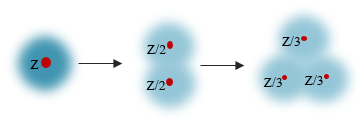

Figure 2: Changing external potential (distribution of positive charge) 

                   leads to rearranging of the electron density in the ground state.

                             $Z=24$: Chromium (Cr)$\to$Magnesium diatomic (Mg$_2$)$\to$Ozone (O$_3$).

**Proof I** : Let's suppose that there exist two potentials $V_{e x t}^{(1)}(\mathbf{r})$ and $V_{e x t}^{(2)}(\mathbf{r})$ differing by more than an additive global constant and giving rise to the same ground state electron density, $\rho_0(\mathbf{r})$. Obviously, $V_{e x t}^{(1)}(\mathbf{r})$ and $V_{e x t}^{(2)}(\mathbf{r})$ produce two distinct Hamiltonians $\hat{H}^{(1)} \neq \hat{H}^{(2)}$, which give rise to two distinct (both normalized to unity) ground states $|\langle \Psi_0^{(1)}| \Psi__0^{(2)}\rangle| \neq 1$, meaning $| \Psi^{(1)}_0 \rangle \neq |  \Psi^{(2)}_0 \rangle$. Because of the variational principle (see live scrip on Hartree method), for systems with non-degenerate ground states we have 


$$E_0^{(1)}=\left\langle\Psi_0^{(1)}\left|\hat{H}^{(1)}\right| \Psi_0^{(1)}\right\rangle<\left\langle\Psi_0^{(2)}\left|\hat{H}^{(1)}\right| \Psi_0^{(2)}\right\rangle\,\, \mathrm{and}\,\,E_0^{(2)}=\left\langle\Psi_0^{(2)}\left|\hat{H}^{(2)}\right| \Psi_0^{(2)}\right\rangle<\left\langle\Psi_0^{(1)}\left|\hat{H}^{(2)}\right| \Psi_0^{(1)}\right\rangle. \qquad (17)$$


Because we assumed to have identical ground state electron densities for the two Hamiltonians, we can rewrite the expectation values in the right-hand-sides of Eqs. (17) as 


$$\begin{array}{cc}\left\langle\Psi_0^{(2)}\left|\hat{H}^{(1)}\right| \Psi_0^{(2)}\right\rangle=\left\langle\Psi_0^{(2)}\left|\hat{H}^{(2)}\right| \Psi_0^{(2)}\right\rangle+\int d \mathbf{r}\left[V_{e x t}^{(1)}(\mathbf{r})-V_{e x t}^{(2)}(\mathbf{r})\right] \rho_{0}(\mathbf{r}).& \qquad (18)\\ \end{array}$$


Exchanging labels in Eq. (18), we obtain 


$$\begin{array}{cc}\left\langle\Psi_0^{(1)}\left|\hat{H}^{(2)}\right| \Psi_0^{(1)}\right\rangle=\left\langle\Psi_0^{(1)}\left|\hat{H}^{(1)}\right| \Psi_0^{(1)}\right\rangle+\int d \mathbf{r}\left[V_{e x t}^{(2)}(\mathbf{r})-V_{e x t}^{(1)}(\mathbf{r})\right] \rho_{0}(\mathbf{r})& \qquad (19)\\ \end{array}$$
 

Adding Eq. (18) and Eq. (19), we obtain


$$\begin{array}{cc}  \left\langle\Psi_0^{(2)}\left|\hat{H}^{(1)}\right| \Psi_0^{(2)}\right\rangle+\left\langle\Psi_0^{(1)}\left|\hat{H}^{(2)}\right| \Psi_0^{(1)}\right\rangle  =E_0^{(2)}+E_0^{(1)},& \qquad (20)\\ \end{array}$$


which is a clear contradiction, since we showed in Eqs. (17) that $\ \left\langle\Psi_0^{(2)}\left|\hat{H}^{(1)}\right| \Psi_0^{(2)}\right\rangle+\left\langle\Psi_0^{(1)}\left|\hat{H}^{(2)}\right| \Psi_0^{(1)}\right\rangle  >E_0^{(1)}+E_0^{(2)}$.

Hence we proved that if ground state electron densities are the same, then external potentials must be the same as well (up to a global constant). Since the remaining terms of the total Hamiltonian (first and third terms in Eq. (3)) the kinetic energy $-\frac{1}{2} \sum_{i}^{N} \nabla_{i}^{2}$ and the electron-electron interaction energy  $\frac{1}{2} \displaystyle\sum_{i}^{N} \sum_{j \neq i}^{N} \frac{1}{\mid \mathbf{r}_{i}-\mathbf{r}_{j} \mid}$ both  have the universal (fixed) expression for any $N$-electron system (system of atoms when $N_n=1$ in Eq. (3), molecules when $N_n>1$ in Eq. (3), crystals, jellium model, surfaces, nanowires differ from each other only by $V_{ext} (\mathbf{r})$), and since $N$ is as well determined by $\rho_0(\mathbf{r})$, this also implies that not only the external potential, but also **the total Hamiltonian in Eq. (****3****) is also specified up to a global constant **$\hat \bar H=\hat H+const\cdot N$** by **$\rho_0(\mathbf{r})$. Hence the ground state (and all other eigen states) and expectation values of operators such as the kinetic energy and the electron-electron interaction energy are specified uniquely. This is indicated in the flow depicted in Fig. 3. 

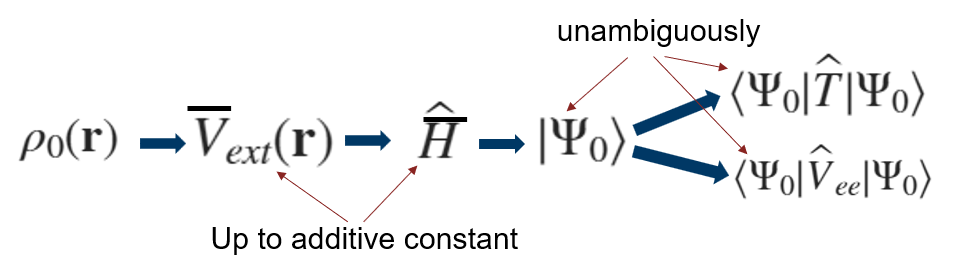

Figure 3: The ground state electron density determining all other quantities unambiguously, 

                or up to an additive global constant (variables with bar). Note that the ground state

         wave function $| \Psi_0\rangle$ also determines $V_{ext}$ only up to a global additive constant.

Since the ground state $| \Psi_0\rangle$ is uniquely specified by $\rho_0(\mathbf{r})$ and the Hamiltonian is specified up to a global additive constant (due to the specification of $\rho_0(\mathbf{r})\to \bar V_{ext}(\mathbf{r})=V_{ext}(\mathbf{r})+const$ up to a global additive constant), it means that the ground state electron density unambiguously specifies the following difference: 


$$\langle \Psi_0(\rho_0)| \hat \bar H| \Psi_0(\rho_0) \rangle-\int \rho_0( \mathbf{r})\bar V_{ext}(\mathbf{r})d\mathbf{r}=\bar E_0-\int \rho_0( \mathbf{r})\bar V_{ext}(\mathbf{r})d\mathbf{r}.\qquad (21)$$


On the other hand, the difference between the ground state energy $\bar E_0$ and $\int \rho_0(\mathbf{r}) \bar V_{ext}(\mathbf{r}) d \mathbf{r}$ (for any $N$- electron system) can be represented as a universal (not depending on $V_{ext}$) functional of the ground state electron density $\langle\Psi_0 (\rho_0) | \left(\hat T+\hat V_{ee}\right) | \Psi_0 (\rho_0)\rangle=(T+V_{ee})[\rho_0]$ [**]: 


$$\bar E_0-\int \rho_0( \mathbf{r})\bar V_{ext}(\mathbf{r})d\mathbf{r}=\langle\Psi_0 (\rho_0) | \left(\hat T+\hat V_{ee}\right) | \Psi_0 (\rho_0)\rangle =E_0-\int \rho_0(\mathbf{ r}) V_{ext}(\mathbf{r})d\mathbf{r}.\qquad(22)$$


This immediately suggests for $N$ - electron system to treat** ground state energy **$E_0$** (a number) as a functional (since that number depends on **$\rho_0(\mathbf{r})$** - a scalar function over the 3D space) of the ground state electron density** $E_0 = E[\rho_0]$. We will see below that it is in fact a unique functional, meaning that $E[\rho_0]\neq E[\rho]$ if $\rho(\mathbf{r}) \neq \rho_0(\mathbf{r})$, where


$$E[\rho_0] =(T+V_{ee})[\rho_0]+ \int \rho_0(\mathbf{r})  V_{ext}(\mathbf{r}) d \mathbf{r}. \qquad (23)$$


Unlike the Thomas-Fermi model, where energy is defined in terms of a simple functional of density (in the Thomas-Fermi model we denoted $\rho_{0}=\rho_{TF}$), for real systems we do not know the exact functional dependence of $(T+V_{ee})[]$ on ground state electron density.  Nevertheless, Eq. (23) is used to define the energy functional $E[ \rho]$ for $N$- electron system with the Hamiltonian Eq. (3), by substituting instead of $\rho_0$ arbitrary continuous scalar function $\rho(\mathbf{r})$ such that: $\rho(\mathbf{r})=N\int |\Psi(\mathbf{r},\mathbf{r}_2,...,\mathbf{r}_N)|^2 d\mathbf{r}_2...d\mathbf{r}_N$, where $\Psi$ is fermionic function (antisymmetric with respect to exchanging any of its two arguments) and has a unit norm.

Summarizing the immediate implication of the HK theorem 1: For $N$-electron system described by Hamiltonian Eq. (3) we can define energy functional 


$$E[\rho]=(T+V_{ee})[\rho ]+ \int \rho (\mathbf{r})  V_{ext}(\mathbf{r}) d \mathbf{r} =F[\rho ]+ \int \rho (\mathbf{r})  V_{ext}(\mathbf{r}) d \mathbf{r}, \qquad (24)$$


such that $E[\rho_0]=E_0$, with $E_0$ exact ground state energy of Hamiltonian Eq. (3) $\hat H |\Psi_0\rangle =E_0 |\Psi_0 \rangle$ and $\rho_0( \mathbf{r})=\sum_{i=1}^{N}  \langle \Psi_0 | \delta^3 (\mathbf{\hat r}_i -\mathbf{r}) |\Psi_0\rangle$ exact single-electron ground state density. Furthermore, if the Hamiltonian has non-degenerate ground state $|\Psi_0 \rangle$, then the ground state energy is a unique functional of the ground state electron density given in Eq. (23) - see the proof of uniqueness in the proof of second Hohenberg-Kohn theorem below. 

**The notion of the energy functional **$E[ \rho]$** defined, but not specified, in Eq. (****24****) is the key notion of the DFT.**

**HK theorem II:** The exact ground state energy $E_0$ is the global minimum value of the energy functional $E[\rho]$ given in Eq. (24) and the corresponding electron density is the ground state electron density and no other density $\rho_0( \mathbf{r})=\sum_{i=1}^{N}  \langle \Psi_0 | \delta^3 (\mathbf{\hat r}_i -\mathbf{r}) |\Psi_0\rangle = \arg\min E[\rho]$. It is a remarkable fact that even that we do not know the exact functional form of $E[\rho]$, we still can prove this theorem.

**Proof II**: We want to show that if $\rho(\mathbf{r})=\tilde \rho (\mathbf{r}) \neq \rho_0(\mathbf{r})$ then $E [\tilde \rho]>E[\rho_0]$, and hence $E [\rho_0]= \min\Bigl \{  E[\rho] \Big\}=E_0$.

Theorem II (as in its original formulation) is proved by the variational principle and the assumption of $v$-representablity of the density (and hence it should read as:$E [\rho_0]= \min\Bigl \{  E_v[\rho] \Big\}=E_0$, with subscript $v$ indicating $v$-representebility). Let's take a density $\tilde \rho(\mathbf{r}) \neq \rho_0(\mathbf{r})$ and interpret it as a ground state electron density for a different $\tilde V_{ext} (\mathbf{r}) \neq V_{ext} (\mathbf{r})$ external potential (different must be by more than by a global constant if $\tilde \rho(\mathbf{r}) \neq \rho_0(\mathbf{r})$). Thus Hohenberg and Kohn have assumed that one can find external potential $\tilde V_{ext} (\mathbf{r})$, i. e. rearrange positive charges in such a way, that it produces the ground state electron density $\tilde \rho(\mathbf{r})$. Such densities are called $v$-representable. A generalization of HK theorem II which does not require density to be $v$-representable, but rather $N$-representable was found by Levy and Lieb (density is $N$- representeble if it is obtainable from any $N$-fermionic, antisymmetric, unit normalized wave function $\Psi_{\alpha}$: $\tilde \rho(\mathbf{r})=N\sum_{\sigma_1}\int |\Psi_{\alpha}(\mathbf{r},\mathbf{r}_2,\cdots \mathbf{r}_N)|^2 d\mathbf{r}_2...d\mathbf{r}_N$). If external potential $\tilde V_{ext} (\mathbf{r})$ that produces $\tilde \rho({\mathbf{r})$ exists, then $\tilde \rho({\mathbf{r})$ defines another Hamiltonian $\hat \tilde H$ that has ground state $| \tilde \Psi_0 \rangle \neq |  \Psi_0 \rangle$ such that $\tilde \rho( \mathbf{r})=\sum_{i=1}^{N}  \langle \tilde \Psi_0| \delta^3 (\mathbf{\hat r}_i -\mathbf{r}) |\tilde \Psi_0\rangle$. When using $| \tilde \Psi_0 \rangle$ as a trial variational state for calculating expectation value of $\hat H$ we get,


$$E\left[\rho_0\right]=\langle\Psi_0\left|\hat{H}\right| \Psi_0 \rangle  <  \langle \tilde \Psi_0 \left| \hat{H} \right| \tilde \Psi_0 \rangle  = E\left[\tilde \rho \right].\qquad (25)$$


The strict inequality $\langle\Psi_0\left|\hat{H}\right| \Psi_0 \rangle  <  \langle \tilde \Psi_0 \left| \hat{H} \right| \tilde \Psi_0 \rangle$ follows simply from the basic variational principle (and the fact that the ground state of $\hat H$ is non degenerate). The last equality in (25) $\langle \tilde \Psi_0 \left| \hat{H} \right| \tilde \Psi_0 \rangle  = E\left[\tilde \rho \right]$however needs derivation that we provide below. From the definition of the energy functional in Eq. (24) we have:


$$E[\tilde \rho]=  F[\tilde \rho] +E_{en} [\tilde \rho]   \\ \qquad= F [\tilde \rho] +\int  V_{ext}(\mathbf{r}) \tilde \rho(\mathbf{r}) d\mathbf{r}\  \\ \qquad=F [\tilde \rho]  + \int \tilde V_{ext}(\mathbf{r}) \tilde \rho(\mathbf{r}) d\mathbf{r} +  \int \Big(V_{ext}(\mathbf{r})-\tilde V_{ext}(\mathbf{r}) \Big)\tilde \rho(\mathbf{r}) d\mathrm{r} \\ \qquad =\tilde E_0 +  \int \Big(V_{ext}(\mathbf{r})-\tilde V_{ext}(\mathbf{r}) \Big)\tilde \rho(\mathbf{r}) d\mathbf{r}, \qquad  (26)$$


where $\tilde E_0=  \langle \tilde \Psi_0| \hat \tilde H  |\tilde \Psi_0 \rangle=F[\tilde \rho]  + \int \tilde V_{ext}(\mathbf{r}) \tilde \rho (\mathbf{r}) d\mathbf{r}$ is the ground state energy corresponding to the electron system with ground state density $\tilde \rho$ and the ground state $|\tilde \Psi_0\rangle$, with the same universal $\hat T$ and $\hat V_{ee}$ operators, $\langle \tilde \Psi_0 |\hat \tilde V_{en} | \tilde \Psi_0 \rangle= \int \tilde V_{ext}(\mathbf{r}) \tilde \rho(\mathbf{r}) d\mathbf{r}$ and Hamilton operator $\hat \tilde H=\hat T+ \hat \tilde V_{en} +\hat V_{ee}=\hat H - \hat V_{en}+\hat \tilde V_{en}$. Hence we have from Eq. (26):


$$E[\tilde \rho]=  \langle \tilde \Psi_0| \hat \tilde H  |\tilde \Psi_0 \rangle+ \int \Big(V_{ext}(\mathbf{r})-\tilde V_{ext}(\mathbf{r}) \Big)\tilde \rho(\mathbf{r}) d\mathbf{r}=\langle \tilde \Psi_0| \hat H  |\tilde \Psi_0 \rangle>  \langle \Psi_0| \hat H  | \Psi_0 \rangle =E_0=E[\rho_0],$$


where we used that equation: $<\alpha | \hat V_{en}|\alpha>= \int V_{ext} (\mathbf{r}) \rho_{\alpha}(\mathbf{r}) d\mathbf{r}$  (with $\rho_{\alpha}( \mathbf{r})=\sum_{i=1}^{N}  \langle \alpha| \delta^3 (\mathbf{\hat r}_i -\mathbf{r}) |\alpha\rangle$ - single-electron density in state $|\alpha \rangle$), holds true in any $N$-electron state $|\alpha \rangle$, not only in the ground state. Here $|\alpha \rangle= |\tilde \Psi_0 \rangle$ and it is not the ground state for the original Hamiltonian $\hat H$ and $\rho_{\alpha}=\tilde \rho$.

Note, in deriving Eq. (26) we have used that the functional form of $F[]=(T+V_{ee})[]$ does not depend on $\rho_0(\mathbf{r})$ and is universal [**], independent of $V_{ext}$, and hence, we took the same universal functional when calculating $\tilde E_0=  \langle \tilde \Psi_0| \hat \tilde H  |\tilde \Psi_0 \rangle=F[\tilde \rho]  + \int \tilde V_{ext}(\mathbf{r}) \tilde \rho (\mathbf{r}) d\mathbf{r}$.

It follows that by minimizing with respect to $\rho(\mathbf{r})$ of the energy functional $E[\rho]$ as defined in Eq. (24), one finds the lowest possible energy (or, in other words, the ground state energy) of the electron system defined by Hamiltonian in Eq. (3). The density that minimizes the energy functional in Eq. (24) is unique and it is the ground state electron density: 


$$\arg\min E[\rho]=\sum_{i=1}^{N}  \langle \Psi_0 | \delta^3 (\mathbf{\hat r}_i -\mathbf{r}) |\Psi_0\rangle = \rho_0(\mathbf{r}).\qquad (27)$$


## ** Exercises**

**Exercise 1:** Assume that there is no spin quantum number involved in the problem and using Eq. (9a) calculate $\Delta\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)$ for Hartree and Hartree-Fock approximations for $N$-electron wave function.

- Hartree approximation is a simple product of single-particle wave functions, $\Psi_{\mathrm{Hartree}}\left(\mathbf{r}_1, \mathbf{r}_2,\cdots, \mathbf{r}_N\right)=\psi(\mathbf{r}_1) \psi(\mathbf{r}_2)... \psi(\mathbf{r}_N)$ 

- Hartree-Fock approximation assumes a Slater determinant for wave function 


$$\begin{array}{cc}\Psi_{\mathrm{Hartree-Fock}}\left(\mathbf{r}_1, \mathbf{r}_2, \ldots \mathbf{r}_N\right)=\frac{1}{\sqrt{N !}} \left|\begin{array}{cccccccccccccc}\psi_1\left(\mathbf{r}_1\right) & \psi_2\left(\mathbf{r}_1\right) & \cdots & \psi_N\left(\mathbf{r}_1\right) \\\psi_1\left(\mathbf{r}_2\right) & \psi_2\left(\mathbf{r}_2\right) & \cdots & \psi_N\left(\mathbf{r}_2\right) \\\vdots & \vdots & \ddots & \vdots \\\psi_1\left(\mathbf{r}_N\right) & \psi_2\left(\mathbf{r}_N\right) & \cdots & \psi_N\left(\mathbf{r}_N\right)\\ \end{array}\right|&\\ \end{array}.$$


For the Hartree case you should obtain: $2\Delta\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)=  -\displaystyle\sum_{m=1}^N | \psi_m (\mathbf{r})|^2 | \psi_m (\mathbf{r'})|^2$, hence it is entirely self-interaction and $\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)= \rho(\mathbf{r}) \rho(\mathbf{r}^{\prime})/2 - \displaystyle\sum_{m=1}^N | \psi_m (\mathbf{r})|^2 | \psi_m (\mathbf{r'})|^2/2$.

For the Hartree-Fock case, when antisymmetrization of $N$-electron state is imposed explicitely, you should obtain: $2\Delta\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)=  -|\displaystyle\sum_{j=1}^N  \psi^*_j (\mathbf{r})  \psi_j (\mathbf{r'})|^2$, which includes both self-interaction and exchange interaction between similar spin electrons. 

Hint: Assume for simplicity that space is one-dimensional and use orthonormalization property of single-particle states: $\int \psi^*_n(\mathbf{r}) \psi_m(\mathbf{r}) d\mathbf{r} \to \int  \psi^*_n(x) \psi_m(x) dx =\delta_{n,m}$.

We will use symbolic calculation for $N=2$ case to calculate $\langle  \Psi|    \hat \rho(x)  \hat \rho(x')  |\Psi \rangle$, where $\hat\rho(x)=\delta \left(x-\hat x_1\right)+ \delta \left(x-\hat x_2\right)$. We will introduce following denotions: $\rho_m(x)=|\psi_m(x)|^2$, for $m=1,2$ and hence in Slater determinnat state: $\rho(x)=\rho_1(x)+\rho_2(x)$.

N=2;
syms x1 x2 x x_prime real
syms psi1(x1) psi2(x2) rho(x) rho1(x) rho2(x)
A=[psi1(x1) psi1(x2); psi2(x1), psi2(x2)]

$$A = \left(\begin{array}{cc} \psi_{1}\left(x_{1}\right) & \psi_{1}\left(x_{2}\right)\\ \psi_{2}\left(x_{1}\right) & \psi_{2}\left(x_{2}\right) \end{array}\right)$$

Psi=det(A)/sqrt(factorial(N))

$$Psi = \frac{\sqrt{2}\,\left(\psi_{1}\left(x_{1}\right)\,\psi_{2}\left(x_{2}\right)-\psi_{1}\left(x_{2}\right)\,\psi_{2}\left(x_{1}\right)\right)}{2}$$

Let's first compute $\langle  \Psi|    \delta (x-\hat x_1) \delta (x'-\hat x_1)   |\Psi \rangle  =   \int \Psi^*(x_1,x_2)\delta (x- x_1) \delta (x'- x_1) \Psi(x_1,x_2) dx_1 dx_2$, where first electron coordinate operator $\hat x_1$ inside delta function is replaced by a number - first electron coordinate, since delta functions act on coordinate wave function.

I1=expand(int(int(Psi'*dirac(x - x1)*dirac(x_prime-x1)*Psi, x1, -Inf, Inf), x2, -Inf, Inf))

$$I1 = \frac{\delta (x-x^{\prime })\,\bar{\psi_{1}\left(x\right)}\,\psi_{1}\left(x\right)\,\int_{-\infty }^{\infty }\bar{\psi_{2}\left(x_{2}\right)}\,\psi_{2}\left(x_{2}\right)\mathrm{d}x_{2}}{2}-\frac{\delta (x-x^{\prime })\,\bar{\psi_{1}\left(x\right)}\,\psi_{2}\left(x\right)\,\int_{-\infty }^{\infty }\bar{\psi_{2}\left(x_{2}\right)}\,\psi_{1}\left(x_{2}\right)\mathrm{d}x_{2}}{2}-\frac{\delta (x-x^{\prime })\,\bar{\psi_{2}\left(x\right)}\,\psi_{1}\left(x\right)\,\int_{-\infty }^{\infty }\bar{\psi_{1}\left(x_{2}\right)}\,\psi_{2}\left(x_{2}\right)\mathrm{d}x_{2}}{2}+\frac{\delta (x-x^{\prime })\,\bar{\psi_{2}\left(x\right)}\,\psi_{2}\left(x\right)\,\int_{-\infty }^{\infty }\bar{\psi_{1}\left(x_{2}\right)}\,\psi_{1}\left(x_{2}\right)\mathrm{d}x_{2}}{2}$$

Then we simplify the above answer using orthonormality property $\int_{-\infty}^{\infty}  \overline{\psi_i(x_2)} \psi_j(x_2) dx_2 =\delta_{i,j}$.

I2=subs(I1, [int(psi1(x2)'*psi2(x2), x2,-inf, inf), int(psi1(x2)'*psi1(x2), x2,-inf, inf), int(psi2(x2)'*psi2(x2), x2,-inf, inf), int(psi2(x2)'*psi1(x2), x2,-inf, inf)], [0, 1, 1, 0])

$$I2 = \frac{\delta (x-x^{\prime })\,\bar{\psi_{1}\left(x\right)}\,\psi_{1}\left(x\right)}{2}+\frac{\delta (x-x^{\prime })\,\bar{\psi_{2}\left(x\right)}\,\psi_{2}\left(x\right)}{2}$$

simplify(subs(I2,psi1(x)'*psi1(x),rho(x)-psi2(x)'*psi2(x)))

$$ans = \frac{\delta (x-x^{\prime })\,\rho \left(x\right)}{2}$$

We just obtained: $\langle \Psi| \delta (x-\hat x_1) \delta (x'-\hat x_1)|\Psi \rangle =\delta(x-x')\rho(x)/2$, which does not depend on $x_1$ and thus the same result holds for $\langle \Psi| \delta (x-\hat x_2) \delta (x'-\hat x_2)|\Psi \rangle$.

Next we compute $\langle \Psi| \delta (x-\hat x_1) \delta (x'-\hat x_2)|\Psi \rangle$ 

I3=expand(int(int(Psi'*dirac(x - x1)*dirac(x_prime-x2)*Psi, x1, -Inf, Inf),x2, -Inf, Inf))

$$I3 = \frac{\bar{\psi_{1}\left(x\right)}\,\bar{\psi_{2}\left(x^{\prime }\right)}\,\psi_{1}\left(x\right)\,\psi_{2}\left(x^{\prime }\right)}{2}-\frac{\bar{\psi_{1}\left(x\right)}\,\bar{\psi_{2}\left(x^{\prime }\right)}\,\psi_{2}\left(x\right)\,\psi_{1}\left(x^{\prime }\right)}{2}-\frac{\bar{\psi_{2}\left(x\right)}\,\bar{\psi_{1}\left(x^{\prime }\right)}\,\psi_{1}\left(x\right)\,\psi_{2}\left(x^{\prime }\right)}{2}+\frac{\bar{\psi_{2}\left(x\right)}\,\bar{\psi_{1}\left(x^{\prime }\right)}\,\psi_{2}\left(x\right)\,\psi_{1}\left(x^{\prime }\right)}{2}$$

subs (I3, [psi1(x)'*psi1(x),psi1(x_prime)'*psi1(x_prime), psi2(x)'*psi2(x),psi2(x_prime)'*psi2(x_prime),], [rho1(x),rho1(x_prime),rho2(x),rho2(x_prime)])

$$ans = \frac{\rho_{1}\left(x\right)\,\rho_{2}\left(x^{\prime }\right)}{2}+\frac{\rho_{2}\left(x\right)\,\rho_{1}\left(x^{\prime }\right)}{2}-\frac{\bar{\psi_{1}\left(x\right)}\,\bar{\psi_{2}\left(x^{\prime }\right)}\,\psi_{2}\left(x\right)\,\psi_{1}\left(x^{\prime }\right)}{2}-\frac{\bar{\psi_{2}\left(x\right)}\,\bar{\psi_{1}\left(x^{\prime }\right)}\,\psi_{1}\left(x\right)\,\psi_{2}\left(x^{\prime }\right)}{2}$$

We now check that the same result as for $\langle \Psi| \delta (x-\hat x_1) \delta (x'-\hat x_2)|\Psi \rangle$ holds also for $\langle \Psi| \delta (x-\hat x_2) \delta (x'-\hat x_1)|\Psi \rangle$ 

I4=expand(int(int(Psi'*dirac(x - x2)*dirac(x_prime-x1)*Psi, x1, -Inf, Inf),x2, -Inf, Inf))

$$I4 = \frac{\bar{\psi_{1}\left(x\right)}\,\bar{\psi_{2}\left(x^{\prime }\right)}\,\psi_{1}\left(x\right)\,\psi_{2}\left(x^{\prime }\right)}{2}-\frac{\bar{\psi_{1}\left(x\right)}\,\bar{\psi_{2}\left(x^{\prime }\right)}\,\psi_{2}\left(x\right)\,\psi_{1}\left(x^{\prime }\right)}{2}-\frac{\bar{\psi_{2}\left(x\right)}\,\bar{\psi_{1}\left(x^{\prime }\right)}\,\psi_{1}\left(x\right)\,\psi_{2}\left(x^{\prime }\right)}{2}+\frac{\bar{\psi_{2}\left(x\right)}\,\bar{\psi_{1}\left(x^{\prime }\right)}\,\psi_{2}\left(x\right)\,\psi_{1}\left(x^{\prime }\right)}{2}$$

I3-I4

$$ans = 0$$

Summing up all 4 terms we obtain: $\langle  \Psi|    \hat \rho(x)  \hat \rho(x')  |\Psi \rangle= \delta(x-x') \rho(x) +\rho_1(x) \rho_2(x')+\rho_1(x') \rho_2(x)- \psi^*_1(x) \psi^*_2(x') \psi_2(x) \psi_1(x') - \psi^*_2(x) \psi^*_1(x') \psi_1(x) \psi_2(x')$.

Hence we obtain: $\Delta \rho^{(2)}\left(x,x' \right)= \langle  \Psi|    \hat \rho(x)  \hat \rho(x')  |\Psi \rangle/2 -\rho(x) \big(\delta(x -x') +\rho(x')\big)/2  =-\big(\rho_1(x) \rho_1(x') +\rho_2(x) \rho_2(x') +\psi^*_1(x) \psi^*_2(x') \psi_2(x) \psi_1(x') + \psi^*_2(x) \psi^*_1(x') \psi_1(x) \psi_2(x')\big)/2=  -|\sum_{j=1}^N  \psi^*_j (x)  \psi_j (x')|^2/2$.

In Hartree-Fock approach the correction term $\Delta\rho^{(2)}(x,x')$ subtracts self-interaction from $\rho(x)\rho(x') /2$ and adds exchange interaction to it.

**Exercise 2:** Add spin variables to the problem and for the case of $N=4$ consider the following Slater state: 


$$\begin{array}{cc}\Psi\left(\mathbf{r}_1, \mathbf{r}_2 ,\mathbf{r}_3, \mathbf{r}_4 \right)=\frac{1}{\sqrt{4 !}} \left|\begin{array}{cccccccccccccc}\phi_1\left(\mathbf{r}_1\right)  |\uparrow \rangle_1& \phi_2 \left(\mathbf{r}_1\right) |\downarrow \rangle_1 & \phi_3 \left(\mathbf{r}_1\right) |\uparrow \rangle_1 &   \phi_4 \left(\mathbf{r}_1\right) |\downarrow\rangle_1     \\\phi_1\left(\mathbf{r}_2\right)  |\uparrow\rangle_2& \phi_2 \left(\mathbf{r}_2\right) |\downarrow \rangle_2 & \phi_3 \left(\mathbf{r}_2\right) |\uparrow \rangle_2 &   \phi_4 \left(\mathbf{r}_2\right) |\downarrow \rangle_2  \\\phi_1\left(\mathbf{r}_3\right)  |\uparrow \rangle_3& \phi_2 \left(\mathbf{r}_3\right) |\downarrow \rangle_3 & \phi_3 \left(\mathbf{r}_3\right) |\uparrow \rangle_3 &   \phi_4 \left(\mathbf{r}_3\right) |\downarrow \rangle_3     \\\phi_1\left(\mathbf{r}_4\right)  |\uparrow \rangle_4& \phi_2 \left(\mathbf{r}_4\right) |\downarrow \rangle_4 & \phi_3 \left(\mathbf{r}_4\right) |\uparrow \rangle_4 &   \phi_4 \left(\mathbf{r}_4\right) |\downarrow \rangle_4 \\\end{array}\right|. & \\ \end{array}$$


Calculate $2\Delta\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)$ in this state, using orthonormality property also of spin states: $_j\langle \sigma| \tilde \sigma\rangle_j=\delta_{\sigma, \tilde \sigma}$. Orthogonality of different spin states is the reason why exchange interaction is present only between the same-spin electrons.

In case $\phi_1=\phi_2$ are $1s$ orbitals and $\phi_3=\phi_4$ are $2s$ orbitals, $\Psi$ can describe berylium ground state $1s^22s^2$. 

Correction term, when including spin part explicitely, is: $\displaystyle\Delta\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)=  - \frac{1}{2}\sum_{n,m=1}^N\sum_{\sigma_m, \sigma_n} \delta_{\sigma_m,  \sigma_n}  \phi^*_m (\mathbf{r})  \phi_m (\mathbf{r'})    \phi^*_n (\mathbf{r'})  \phi_n (\mathbf{r}).$

What the decomposition of $N$-body states into the product of single-electron orbitals misses is many-body correlation effects. In weakly correlated many-body states $|\Psi\rangle$, the correlation effects are small and in strongly correlated states they are large. Systems which have strongly correlated ground states (low-dimensional systems in general) are called strongly correlated systems. DFT (as well as Hartree-Fock) performs poorly in strongly correlated systems due to the fact that such systems are less tolerable to approximations used for calculating correlation contribution that is beyond Hartree-Fock approximation.

[*] $\rho(\mathbf{r}) d\mathbf{r}/N$ can be interpreted as a probability of finding $i-$th electron (say probability of finding first electron) in infinitesimal 3D volume $d\mathbf{r}$ around point $\mathbf{r}$ in many-electron state $|\Psi \rangle$. Treating electrons as non-interacting and non-correlated particles (forgetting Pauli exclusion principle), probability of finding any of the $N$ electrons (first, or second, or... $N$-th) in volume $d\mathbf{r}$ is: $1-\left(1-\frac{\rho(\mathbf{r}) d\mathbf{r}}{N}\right)^N\simeq \rho(\mathbf{r}) d\mathbf{r}+o(d\mathbf{r}^2)$. Note that probability of finding any of the $N$ electrons in some volume $\Omega$ is 

$1-\left(1-\frac{ \int_{\Omega }\rho(\mathbf{r}) d\mathbf{r}}{N}\right)^N$,

and $1-\left(1-\frac{ \int_{\Omega }\rho(\mathbf{r}) d\mathbf{r}}{N}\right)^N \neq \int_{\Omega} \rho(\mathbf{r}) d\mathrm{r}$. In particular, probability of finding any of $N$ electrons anywhere in 3D space is the same as probability of finding $i$-th electron anywhere and equals $1$. 

[**] Given $\rho_0(\mathbf{r})$ we can immediately obtain $N$, the total number of electrons - an upper bound for summation in definitions of operators $\hat T$ and $\hat V_{ee}$. Hence expressions of these operators are uanmbiguously specified by $\rho_0(\mathbf{r})$. Moreover, as we showed, the ground state expectation value $\langle \Psi_0 (\rho_0)| \left(\hat T+\hat V_{ee}\right)| \Psi_0(\rho_0)\rangle$ is also unambiguously specified by $\rho_0(\mathbf{r})$. Hence we can regard $\langle \Psi_0 (\rho_0)| \left(\hat T+\hat V_{ee}\right)| \Psi_0(\rho_0)\rangle$ as a functional of the ground state electron density: $\langle \Psi_0 (\rho_0)| \left(\hat T+\hat V_{ee}\right)| \Psi_0(\rho_0)\rangle=(T+V_{ee})[\rho_0]$. The functional form of $(T+V_{ee})[]$ itself can not depend on $\rho_0(\mathbf{r})$ (and hence on $V_{ext}$), since expressions of the kinetic energy operator and electron-electron interaction operator are universal for any $N$-electron system, unlike the electron-nucleus interaction operator that is different for different systems such as atoms, molecules, crystals. When we write functional as $(T+V_{ee})[\rho_0] = \int \sum_mA_m(\mathbf{r}) \rho_0^{m}(\mathbf{r}) d\mathbf{r}+ \int B(\mathbf{r}) \left( \nabla \rho_0(\mathbf{r}) \right)^2/\rho_0(\mathbf{r}) d\mathbf{r}+\int \int C(\mathbf{r}_1,\mathbf{r}_2) \rho_0(\mathbf{r}_1)  \rho_0(\mathbf{r}_2)d\mathbf{r_1}d\mathbf{r_2}  + \cdots$, i.e. when all $\rho_0$ dependence is written out explicitely, then functions $A_m,B,C,...$ (that may be space dependent) do not carry $\rho_0$ dependence, hence are universal, independent of $V_{ext}$. What changes with changing $V_{ext}(\mathbf{r})$ is $\rho_0(\mathbf{r})$ (see Fig. 2), however the functional dependence of $T$+$V_{ee}$ on $\rho_0(\mathbf{r})$ (analogically of individual functionals $T[\rho]$ and $V_{ee}[\rho]$) stays the same for any $N$-electron system. As generic this functional dependence $(T+V_{ee})[\rho_0]$ is, so impossible is to determine it in an exact way. Following the literature, we have introduced the notation $F[\rho]=T[\rho]+V_{ee}[\rho]$.

Note that for the Homogenous Electron Gas ([jellium](https://en.wikipedia.org/wiki/Jellium#:~:text=Jellium%2C%20also%20known%20as%20the,quantity%20as%20well%20in%20space.)), the simplest interacting electron model with uniform ground state density,$\nabla \rho_0(\mathbf{r})=0$ and hence we can not extract $B(\mathbf{r})$ coefficient from obtaining ground state energy dependence on ground state electron density in HEG.

## References

1.  P. Hohenberg and W. Kohn, [*Inhomogenous Electron Gas*](https://journals.aps.org/pr/pdf/10.1103/PhysRev.136.B864), Phys. Rev. B** 136**, 864 (1964). 

2. W. Kohn and L. J. Sham, [*Self-Consistent Equations Including Exchange and Correlation Effects*](https://journals.aps.org/pr/pdf/10.1103/PhysRev.140.A1133), Phys. Rev. A **140**, 1133 (1965).

3. R. G. Parr and W. Yang, *Density-Functional Theory of Atoms and Molecules*, Oxford University Press, (1995).

4. R. M. Martin, *Electronic structure, Basic Theory and Practical Methods*, Cambridge University Press, (2020).